# Incapacity Episode Analysis (2022-now)

## Data Selection

trailingXMonths = 36; % Trailing X Months (TXM) analysis will be computed below, for specified X months (which are valid/available)
monthsValidDict = dictionary(2022:2025,{7:10,2:12,1:12,1:6}); % hard-coded months with valid (sufficient) data


Identify range of days included within Trailing X Months window:

endDate = datetime("now");
startDate = endDate - calmonths(trailingXMonths-1);

daysStudy_ = startDate:endDate;

Remove days from months without sufficient data for monthly viz/stats: 

daysStudy = daysStudy_;
idx = numel(daysStudy);
for date = daysStudy_(end):-1:daysStudy_(1)
    if ~ismember(month(date), monthsValidDict{year(date)}) %check if month has valid data
        daysStudy(idx) = [];
    end
    idx = idx - 1;
end

Create equal-length month/year arrays identifying trailing X months here: 

%monthsStudy = monthsValidDict{yearStudy}; % use all valid months by default
monthsTXM_ = month(daysStudy);
idx = [1 find(ischange(monthsTXM_))];
monthsTXM = month(daysStudy(idx));
yearsTXM = year(daysStudy(idx));
numMonthsStudy = numel(monthsTXM);


## Data Access & Cleaning

#### Read years of interest from workbook

currentYear = year(datetime("now"));

setenv('AWS_DEFAULT_REGION','us-east-2');
readYearFcn = @(yearVal) readtable('s3://vijayiyer05-me-health-metrics/IncapacityEpisodes.xlsx','Sheet',string(yearVal),'TextType','string');

yearRange = unique(yearsTXM,"stable");
for yy = 1:numel(yearRange)
    if yy == 1
        T = readYearFcn(yearRange(yy));
    else
        T = [T; readYearFcn(yearRange(yy))]; %#ok<AGROW>
    end
end

T = sortrows(T,"Timestamp","ascend");

#### Create and annotate tables for downstream analysis

% Create tables for episode (hourly) & down day tracking
TEpisodes = T(~ismissing(T.Duration),:);
TDowndays = T(~ismissing(T.FourPlusHours),:); 

% Remove any episodes tracked during down days
TEpisodes(ismember(categorical(TEpisodes.Date),categorical(TDowndays.Date)),:) = []; 

% Convert Duration variable to MATLAB duration type
durationTimestamp = datetime(datevec(TEpisodes.Duration)); %represent duration variable as a datetime timestamp
referenceTimestamp = datetime(zeros(1,6)); % start of day on first date

durationVar = durationTimestamp - referenceTimestamp;
TEpisodes.Duration = durationVar; 

% Annotate table w/ categorical month variables
TEpisodes = annotateTable(TEpisodes);
TDowndays = annotateTable(TDowndays);

% Ensure uniform month categories across both tables
TEpisodes.Month = removecats(TEpisodes.Month); % removes unused months
TDowndays.Month = setcats(TDowndays.Month,categories(TEpisodes.Month));

function Tout = annotateTable(Tin)
monthVec = categorical(datetime(year(Tin.Date),month(Tin.Date),1,'Format','MMMM yyyy'),'Ordinal',true); %awkward: lots of steps from month numbers to month categorical
Tout = addvars(Tin,monthVec,'NewVariableNames',"Month");
%Tout.Month = removecats(Tout.Month); % remove unused categories (months)
end


#### Create Trailing X Month tables 

TODO: Consider TXM by row subtraction vs row addition (as done now) to simplify logic

[TEpisodesTXM, TDowndaysTXM] = deal(TEpisodes(1,:)); % clone columns, part 1
TEpisodesTXM(1,:) = []; TDowndaysTXM(1,:) = []; % clone columns, part 2

for idx = 1:numel(monthsTXM)
    m = monthsTXM(idx);
    y = yearsTXM(idx);

    TEpisodesTXM = [TEpisodesTXM;TEpisodes(rows4Month(TEpisodes,m,y),:)]; %#ok<AGROW>
    TDowndaysTXM = [TDowndaysTXM;TDowndays(rows4Month(TDowndays,m,y),:)]; %#ok<AGROW>
end


function rowIdxs = rows4Month(Tin,m,y)
rowIdxs = month(Tin.Date)==m & year(Tin.Date)==y;
end

%TBD if this is needed for either table; expect some zeros for Downdays but
%not for Episodes
%TEpisodesTXM.Month = removecats(TEpisodesTXM.Month);

## Trailing X Months Visualization

#### Visualize episodes across trailing X months with a swarm chart

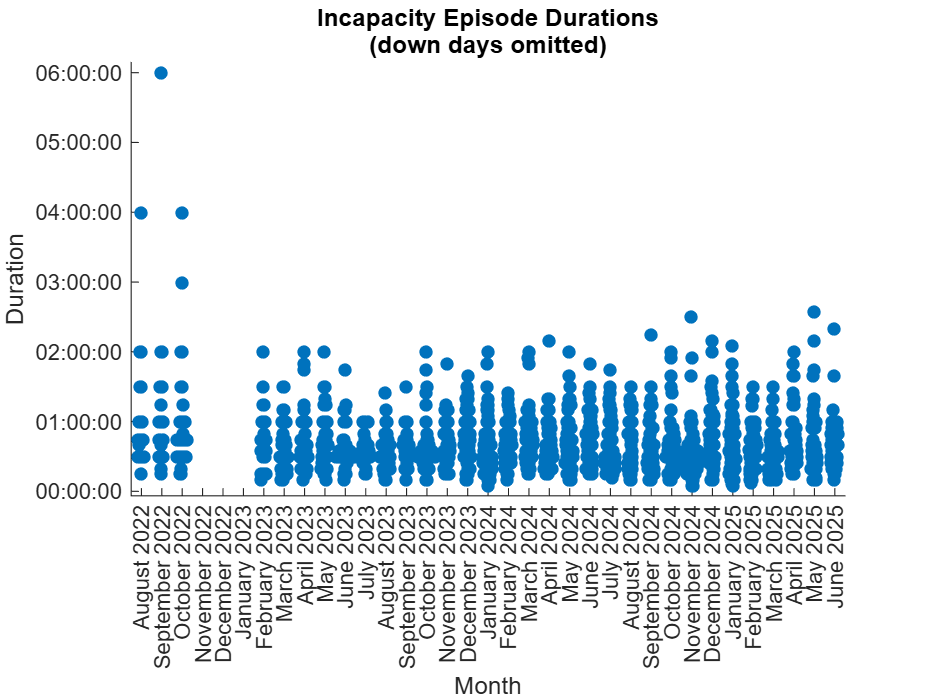

% durationsByMonth = cell(1,numMonthsStudy);
% TSwarm = TStudy(1,:); 
% TSwarm(1,:) = [];
% for idx = 1:numel(monthsStudy)
%     m = monthsStudy(idx);
%     y = yearsStudy(idx);
%     TSwarm = [TSwarm;TStudy(month(TStudy.Date) == m & year(TStudy.Date) == y,:)]; %#ok<AGROW> 
% end
hc = swarmchart(TEpisodesTXM,"Month","Duration","filled");
xlim([min(hc.XData) max(hc.XData)]);
title(["Incapacity Episode Durations";"(down days omitted)"]);

#### Compute raw summary statistics during each month

[medianDuration,meanDuration, numEpisodesByMonth, numDaysTracked, numDownDays] = deal(zeros(numel(monthsTXM),1));

for idx = 1:numel(monthsTXM)
    m = monthsTXM(idx);
    y = yearsTXM(idx);

    % Summary statistics for episodic analyis ('up days')
    TEpisodes_ = TEpisodesTXM(month(TEpisodesTXM.Date) == m & year(TEpisodesTXM.Date) == y,:);

    summaryStruct = summary(TEpisodes_);
    s = summaryStruct.Duration;
    medianDuration(idx) = minutes(s.Median);
    numEpisodesByMonth(idx) = prod(s.Size); % Size is a vector of dimension [numEpisodes 1]

    numDaysTracked(idx) = days(summaryStruct.Date.Max - summaryStruct.Date.Min) + 1;

    meanDuration(idx) = mean(minutes(TEpisodes_.Duration));

    % Summary statistics for down days
    TDowndays_ = TDowndaysTXM(month(TDowndaysTXM.Date) == m & year(TDowndaysTXM.Date) == y,:);
    numDownDays(idx) = height(TDowndays_);
    %TODO: validate there are never multiple rows for any specific day

    % Validation    
    assert(medianDuration(idx) == median(minutes(TEpisodes_.Duration))); % check that different ways of extracting statistic return same result
end

#### Renormalize per-day summary statistics by number-of-days for each month

daysInMonth = zeros(numMonthsStudy,1);

% Determine per-month normalization factor for each month
for idx = 1:numMonthsStudy    
    if month(datetime("now")) == monthsTXM(idx) % mid-month analysis
        daysInMonth(idx) = numDaysTracked(idx);
    else
        calendar_ = calendar(yearsTXM(idx),monthsTXM(idx));
        daysInMonth(idx) = max(calendar_,[],'all');
    end
end

% Renormalize incapacity statistics by days in month
dailyIncapacityByMonth = numEpisodesByMonth.*meanDuration./daysInMonth;

medianDurationRenorm = numEpisodesByMonth.*medianDuration./daysInMonth;
meanDurationRenorm = numEpisodesByMonth.*meanDuration./daysInMonth;


#### Plot summary statistics for each month

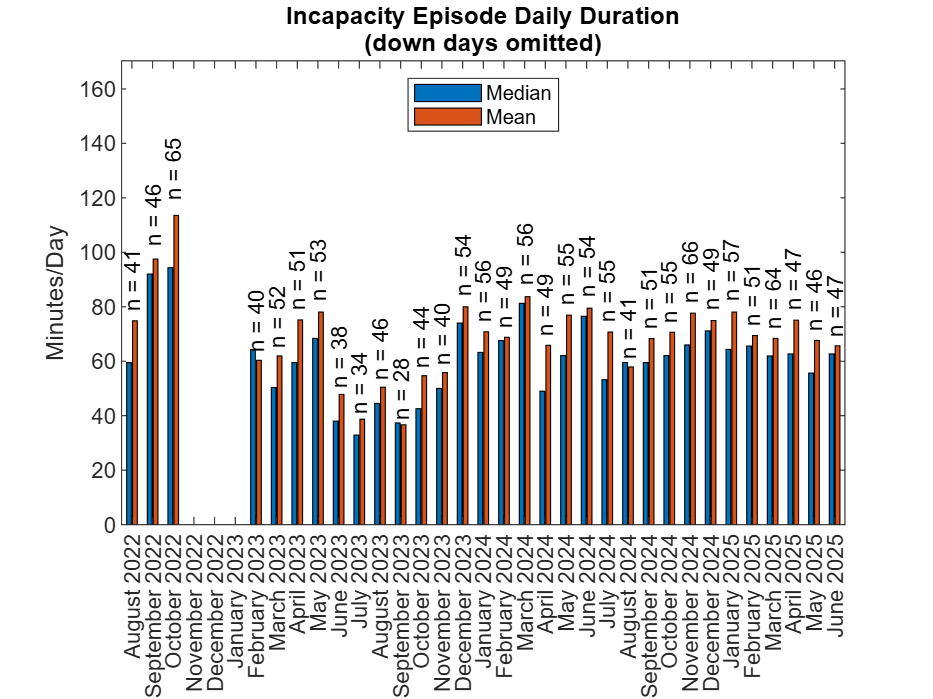

monthLabels = unique(TEpisodesTXM.Month,'stable');

% Plot bar chart of incapacity episode tracking (plus: num episodes label to each month
bar(monthLabels,[medianDurationRenorm meanDurationRenorm]);
xlim([min(monthLabels) max(monthLabels)]);
ylim([0 max([medianDurationRenorm; meanDurationRenorm])*1.5]);
ylabel("Minutes/Day");
legend(["Median" "Mean"],"Location","north");
title(["Incapacity Episode Daily Duration";"(down days omitted)"]);

for idx = 1:numMonthsStudy
    text(monthLabels(idx),meanDurationRenorm(idx)*1.05,"n = " + string(numEpisodesByMonth(idx)),'HorizontalAlignment','left','Rotation',90);
end

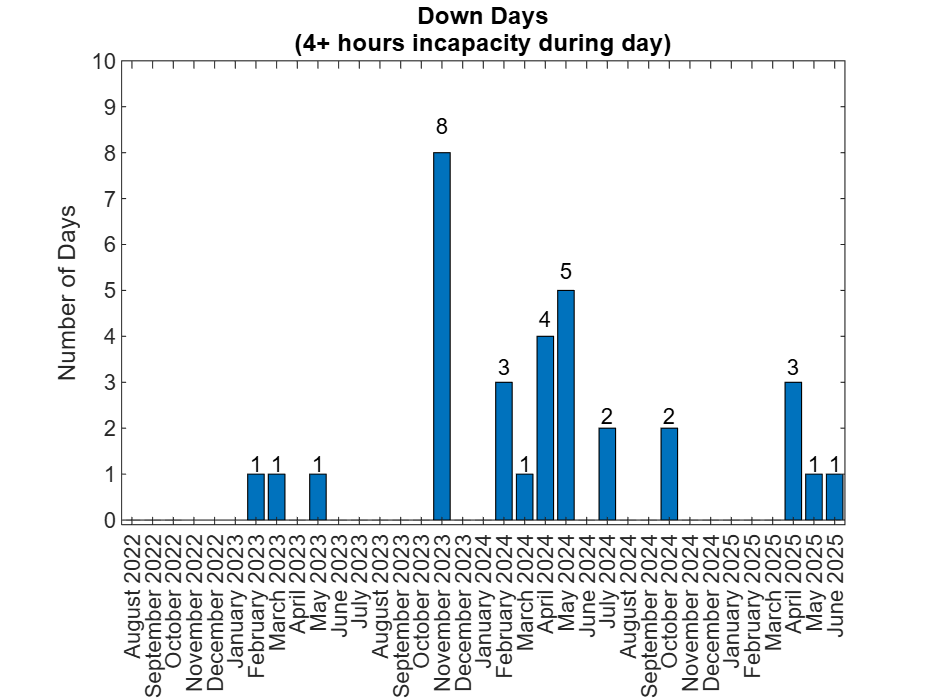


% Plot bar chart of down days (4+ incapacity hours, no epsisodic tracking)
bar(monthLabels,numDownDays);
xlim([min(monthLabels) max(monthLabels)]);
yt = 0:round(max(numDownDays)*1.2);
ylim([-.1 yt(end)]); %make zero baseline visible
yticks(yt);
ylabel("Number of Days");
title(["Down Days"; "(4+ hours incapacity during day)"]);
for idx = 1:numMonthsStudy
    if numDownDays(idx) > 0
        text(monthLabels(idx),numDownDays(idx)*1.05,string(numDownDays(idx)),'HorizontalAlignment','center','VerticalAlignment','baseline');
    end
end

## Last Month Visualization

#### Visualize episodes during a specific month (last month by default)

%monthViz =7;
% monthViz = monthsTXM(end); % most recent month; comment out to select with control above
% yearViz = yearsTXM(end);
% 
% TEpisodes_ = TEpisodesTXM(month(TEpisodesTXM.Date) == monthViz & year(TEpisodesTXM.Date) == yearViz,:);
% 
% hChart = bar(TEpisodes_.Timestamp,TEpisodes_.Duration,'BarWidth',10);
% hChart.EdgeColor = hChart.FaceColor;